## **Uniform**

- Plot the (theoretical) PDF (for contiuous RVs) or PMF (for discrete RVs) and the mean

- Draw a sample of $S=1000$ random outcomes.

- Plot the empirical PDF or PMF of these samples on the same plot created in task 1.

- Plot the (theoretical) CDF

- Plot the empirical CDF of the samples generated in task 2 on the same plot created in task 4.

- Use a Q-Q plot to show the similarity between empirical and theoretical quantiles.

A uniform distribution, sometimes also known as a rectangular distribution, is a distribution that has constant probability.

It can be discrete or continuous

The domain input for PDF exists between [a,b], [upper, lower]

The domain output = 1 / (b-a)

Parameters are the upper and lower bounds. Values can take any numbers

pd = makedist('Uniform', 'lower', 1, 'upper', 3)

pd =   UniformDistribution

  Uniform distribution
    Lower = 1
    Upper = 3


outcomes = 0:0.01:4;
uniform_pdf = pdf(pd, outcomes)

uniform_pdf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


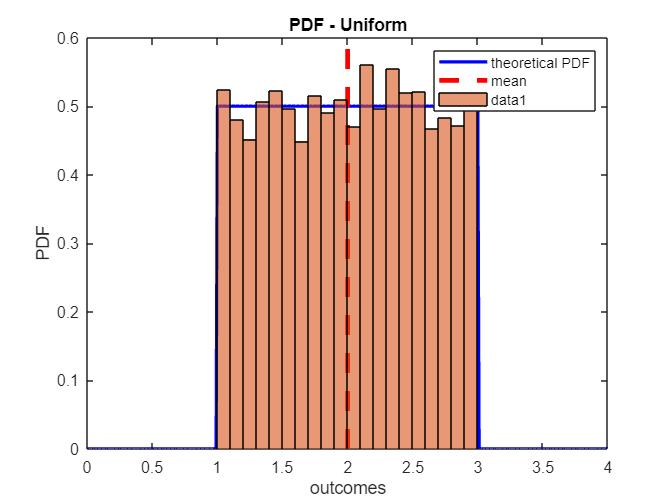

% Create samples
sample = random(pd,1,10000);

% Generate plot data
clf; % clear the figure
plot(outcomes, uniform_pdf, '-b', 'LineWidth', 2)
hold on
uniform_mean = mean(pd); % Let's plot the distribution mean
line([uniform_mean,uniform_mean],[0,0.6], 'LineStyle', '--', 'Linewidth', 3,'Color','red');
legend('theoretical PDF', 'mean', 'Location','northeast')
title('PDF - Uniform') % title for plot
xlabel('outcomes') % x-axis label
ylabel('PDF') % y-axis label

uniform_epmf = histogram(sample, 'normalization', 'pdf'); % correctly normalised

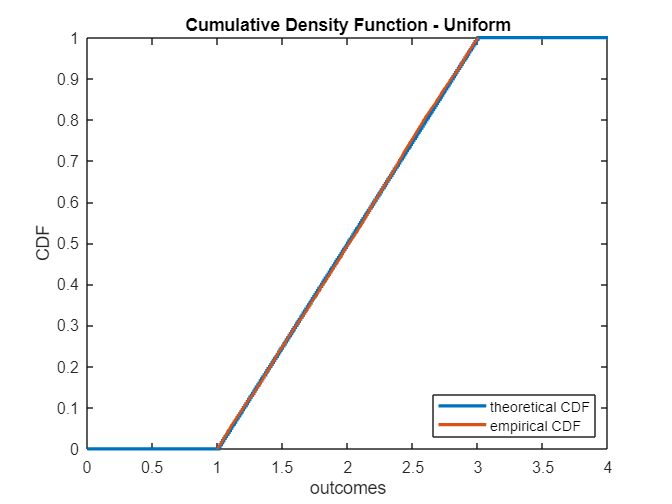

% Create cumulative density function
uniform_cdf = cdf(pd, outcomes);

clf % clear the plot
stairs(outcomes, uniform_cdf, '-', 'LineWidth', 2)
hold on
legend('theoretical CDF', 'Location','southeast')
title('Cumulative Density Function - Uniform') % title for plot
xlabel('outcomes') % x-axis label
ylabel('CDF') % y-axis label

[uniform_ecdf, x] = ecdf(sample);
stairs(x, uniform_ecdf, '-', 'LineWidth', 2)
legend('theoretical CDF','empirical CDF')

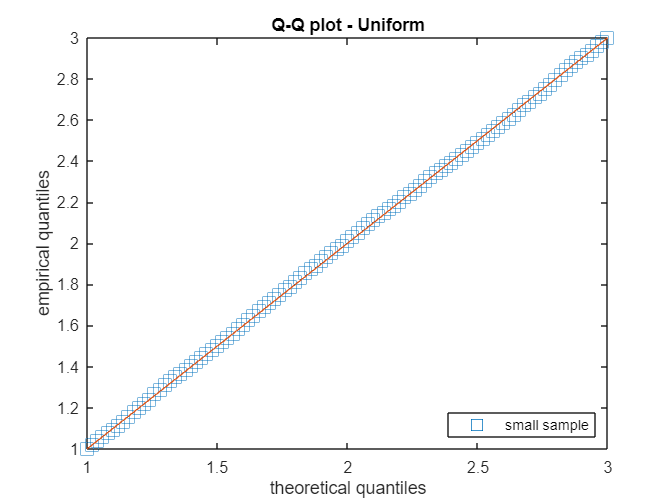

% % evaluate at more points within 0 and 1
pp = 0: 0.01: 1;
clf
theor_q = icdf(pd, pp);
empir_q = quantile(sample, pp);
plot(theor_q, empir_q, 's', 'MarkerSize', 10)
hold on
plot(theor_q, theor_q, '-','HandleVisibility','off')
legend('small sample', 'Location','southeast')
title('Q-Q plot - Uniform') % title for plot
xlabel('theoretical quantiles') % x-axis label
ylabel('empirical quantiles') % y-axis label